## TestFourierSpectrum.m

*need "CalcFourierSpectrum" to show spectra*

*plot figure 2.3*

% ---------------------------------------------------------------
clear 
close all
%---------------------------------------------------------------

%---------------------------------------------------------------
dt = 0.001;
tmax = 4;
t = 0:dt:tmax;
%---------------------------------------------------------------

case 1 - single sine wave

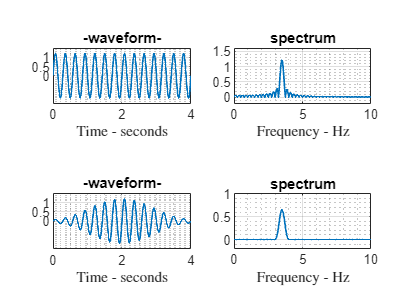

f = 3.5;
xt1 = 1.2*sin(2*pi*f*t);

fmax = 10;
[Xm,  fvec] = CalcFourierSpectrum(xt1, tmax, fmax, false);

figure(1);
clf
% --without window--
subplot(2,2,1);
plot(t, xt1, 'linewidth', 1);

grid('on');
grid('minor');
h = xlabel('Time - seconds');
set(h, 'interpreter', 'latex');
title('-waveform-');
set(gca, 'ylim', [-1.5 1.5]);
%set(gca, 'ylim', [-0.5 1.2]);
%set(gca, 'ylim', [-1.5 1.5]);
%set(gca, 'ylim', [-2.2 2.2]);
set(gca, 'ytick', [0:0.5:1]);
set(gca, 'PlotBoxAspectRatio', [1 .4 1])

subplot(2,2,2);
plot(fvec, Xm, 'linewidth', 1);
grid('on');
grid('minor');
h = xlabel('Frequency - Hz');
title('spectrum');
set(h, 'interpreter', 'latex');
set(gca, 'PlotBoxAspectRatio', [1 .4 1])
set(gca, 'xlim', [0 fmax]);
set(gca, 'ylim', [-0.2 1.6]);
%set(gca, 'ylim', [-0.01 0.055]);
%set(gca, 'ylim', [-0.2 2]);

% --with window--
[Xm,  fvec,Xw] = CalcFourierSpectrum(xt1, tmax, fmax, true);
subplot(2,2,3);
plot(t, Xw, 'linewidth', 1);

grid('on');
grid('minor');
h = xlabel('Time - seconds');
set(h, 'interpreter', 'latex');
title('-waveform-');
set(gca, 'ylim', [-1.5 1.5]);
set(gca, 'ytick', [0:0.5:1]);
set(gca, 'PlotBoxAspectRatio', [1 .4 1]);

subplot(2,2,4);
plot(fvec, Xm, 'linewidth', 1);
grid('on');
grid('minor');
h = xlabel('Frequency - Hz');
title('spectrum');
set(h, 'interpreter', 'latex');
set(gca, 'PlotBoxAspectRatio', [1 .4 1])
set(gca, 'xlim', [0 fmax]);
set(gca, 'ylim', [-0.2 1]);

case 2 - two sine waves

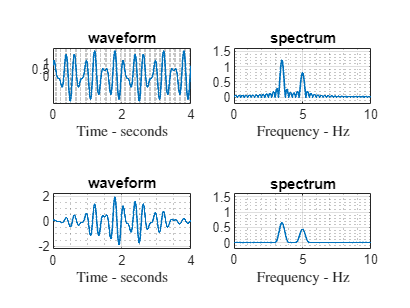

f1 = 3.5;
f2 = 5;
xt2 = 1.2*sin(2*pi*f1*t) + 0.8*cos(2*pi*f2*t) + 0;
fmax = 10;
[Xm,  fvec] = CalcFourierSpectrum(xt2, tmax, fmax, false);
[Xmw, fvec, xtw] = CalcFourierSpectrum(xt2, tmax, fmax, true);
%---------------------------------------------------------------

%---------------------------------------------------------------
figure(1);
clf
subplot(2,2,1);
plot(t, xt2, 'linewidth', 1);

grid('on');
grid('minor');
h = xlabel('Time - seconds');
set(h, 'interpreter', 'latex');
title('waveform');
% set(gca, 'ylim', [-1.2 1.2]);
% set(gca, 'ylim', [-0.5 1.2]);
%set(gca, 'ylim', [-1.5 1.5]);
set(gca, 'ylim', [-2.2 2.2]);
set(gca, 'ytick', 0:0.5:1);
set(gca, 'PlotBoxAspectRatio', [1 .4 1])

subplot(2,2,2);
plot(fvec, Xm, 'linewidth', 1);
grid('on');
grid('minor');
h = xlabel('Frequency - Hz');
title('spectrum');
set(h, 'interpreter', 'latex');
set(gca, 'PlotBoxAspectRatio', [1 .4 1])
set(gca, 'xlim', [0 fmax]);
set(gca, 'ylim', [-0.2 1.6]);
%set(gca, 'ylim', [-0.01 0.055]);
%set(gca, 'ylim', [-0.2 2]);

subplot(2,2,3);
plot(t, xtw, 'linewidth', 1);
grid('on');
grid('minor');
h = xlabel('Time - seconds');
set(h, 'interpreter', 'latex');
title('waveform');
set(gca, 'ylim', [-1.2 1.2]);
set(gca, 'ylim', [-0.5 1.2]);
set(gca, 'ylim', [-2.2 2.2]);
%set(gca, 'ylim', [-1.5 1.5]);
%set(gca, 'ytick', [0:0.5:1]);
set(gca, 'PlotBoxAspectRatio', [1 .4 1])

subplot(2,2,4);
plot(fvec, Xmw, 'linewidth', 1);
grid('on');
grid('minor');
h = xlabel('Frequency - Hz');
set(h, 'interpreter', 'latex');
title('spectrum');
set(gca, 'PlotBoxAspectRatio', [1 .4 1])
set(gca, 'xlim', [0 fmax]);
set(gca, 'ylim', [-0.2 1.6]);

%---------------------------------------------------------------

case 3 - sinc wave

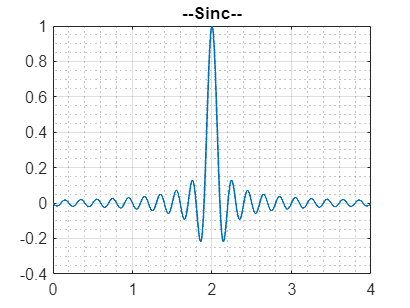

tau = 0.1;
td = 2;
t = 0:dt:tmax;
xt3 = sin(pi*(t-td)/tau + eps)./(pi*(t-td)/tau + eps);

figure(3);
clf
plot(t, xt3,LineWidth=1);
grid('on') ;
grid('minor');
title('--Sinc--')



%---------------------------------------------------------------
